# Excercise 1- Image Data Types

Read a color image and display the image. (imread and imshow)

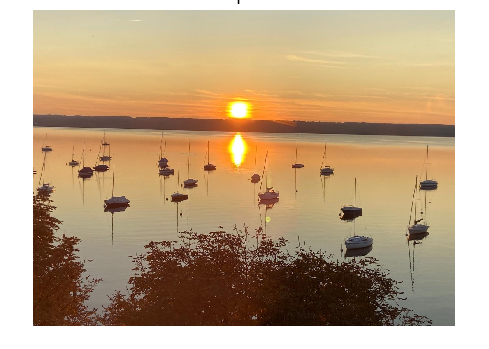

clear  % delete the workspace
clc    % refresh the command window
close all hidden 

img = imread('/home/srb-jarvis/fh_3dimgprocessing/2. Labtask/Bild1.jpg');
imshow(img), title("Original_image rgb")

% info = rendererinfo(gca)

Resize the image so that the maximum from width or height will be 512 and display the new image. (imresize)

[height, width, channel] = size(img)

height = 1200

width = 1600

channel = 3

max_val = max(height, width)

max_val = 1600

scale = 512/max_val

scale = 0.3200

img_scaled = imresize(img,scale);
scled_size = size(img_scaled);

Convert the color image to a gray value image with 256 different gray values. (im2...)

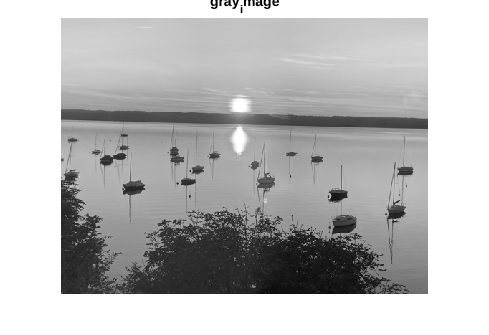

img_gray = im2gray(img_scaled);
imshow(img_gray), title("gray_image")

Convert the color image to an index image with 8 different color values. Display the index image and the corresponding color map. (rgb2...)

[idx, map] = rgb2ind(img_scaled, 8)

idx = 384×512 uint8 matrix
   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6
   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6
   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6
   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6
   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   6   7   6   6   6   6   6   6   6   6   6   6   6   6   6   6 

map =     0.2471    0.1137    0.0471
    0.5647    0.5020    0.4235
    0.8784    0.7647    0.5255
    0.8706    0.5765    0.3059
    0.3961    0.2745    0.2196
    0.8235    0.6588    0.4392
    0.8392    0.7961    0.6549
    0.6745    0.6196    0.5020


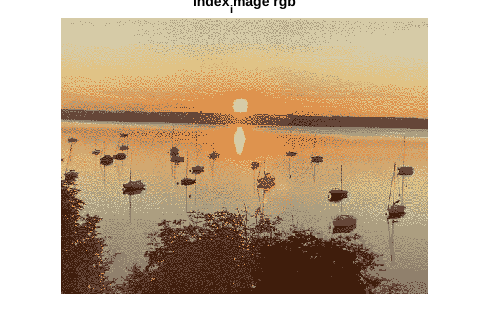

figure
imshow(idx, map), title("index_image rgb")

Create an index image from the gray value image with 8 different gray values. Display the index image and the corresponding color map. Compare the differences between the colored index image and the gray value index image. (gray2...)

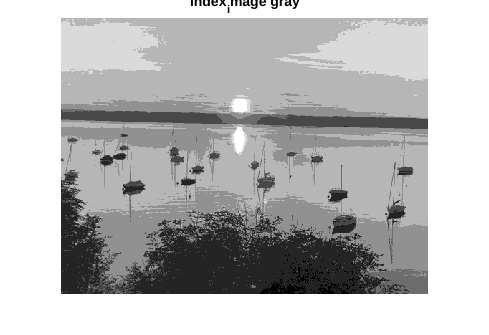

[idx_g, map_g] = gray2ind(img_gray, 8);
figure
imshow(idx_g, map_g), title("index_image gray")

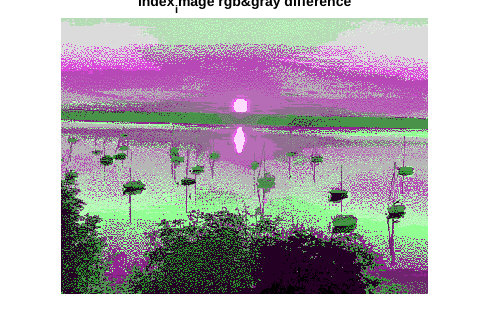


imshowpair(idx, idx_g), title( "index_image rgb&gray difference")

Convert the gray value image into a binary image. What is the default threshold value? (im2...)

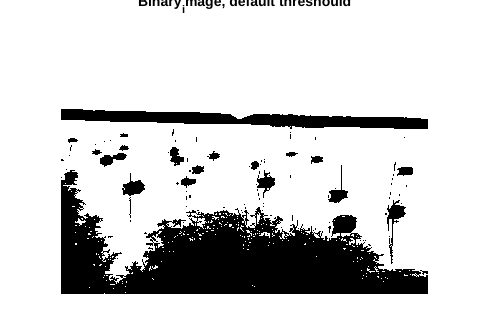

img_binary = imbinarize(img_gray, 0.5);
imshow(img_binary), title("Binary_image, default threshould")

Can you define an optimal threshold value to the gray value image with the otsu algorithm? Display the otsu threshold. 

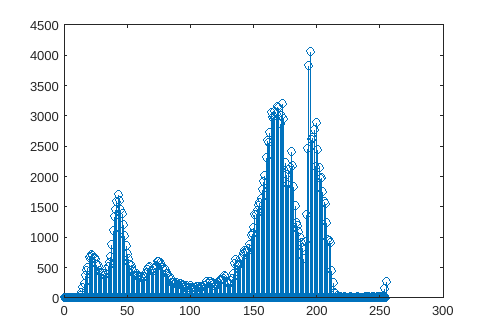

[counts, x] = imhist(img_gray,1024);
stem(x, counts)

Convert the gray value image with the otsu threshold value. Compare the differences between both binary images.

T = otsuthresh(counts)

T = 0.4482

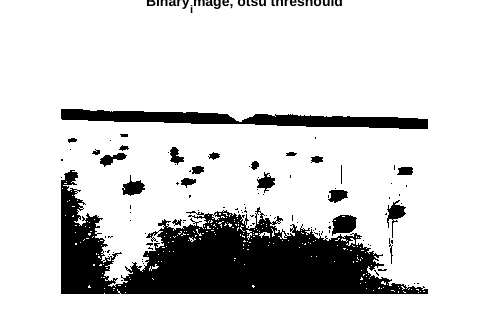

img_binary_otsuthresh = imbinarize(img_gray, T);
imshow(img_binary_otsuthresh), title("Binary_image, otsu threshould")

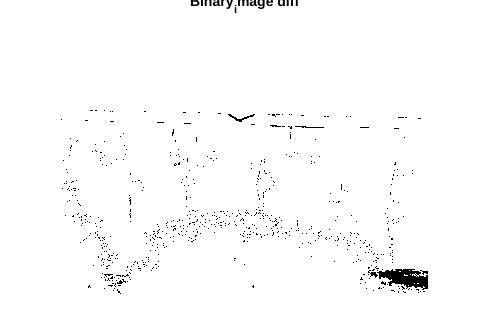


imshow(double(img_binary)-double(img_binary_otsuthresh), []), title("Binary_image diff")

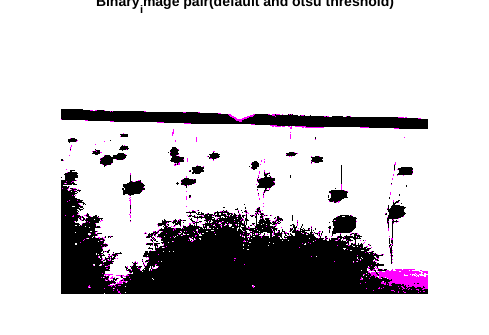

imshowpair(img_binary, img_binary_otsuthresh), title("Binary_image pair(default and otsu threshold)")

Create a negative version from the binary image and show the resulting image. (please use the tilde-operator ~ for boolean data types)

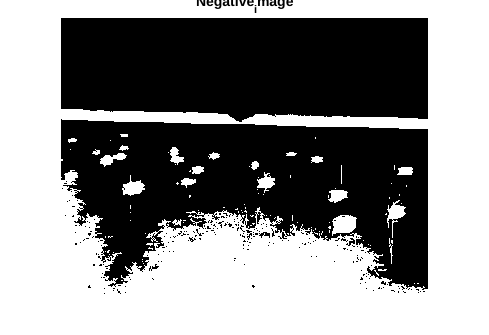

img_negative = ~ img_binary_otsuthresh;
imshow(img_negative), title("Negative_image")